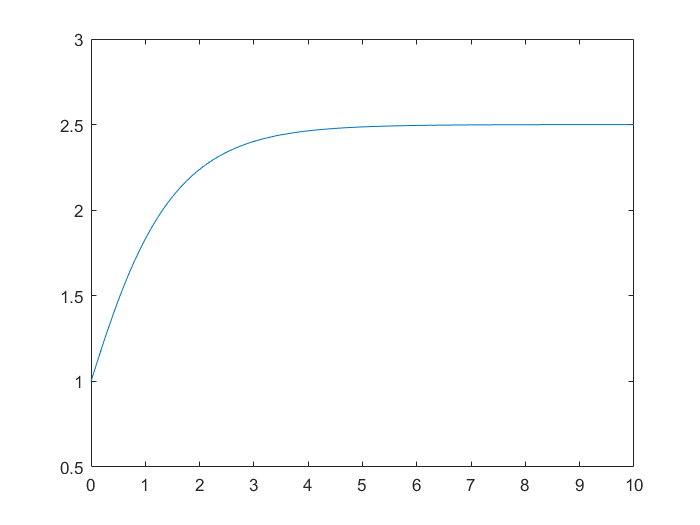

t = 0:0.01:(10);
y = 0.5*exp(-2*t) - 2*exp(-t) + 2.5;
plot(t,y);
xlim([0 10])
ylim([0.5, 3]);

syms y(t)
dy = diff(y, t);
m = diff(y, t, 2) + 3*diff(y,t) + 2*y(t) == 5;
cond1 = y(0) == 1;
cond2 = dy(0) == 1;

conds = [cond1 cond2];

sol(t) = dsolve(m, conds)

$$sol(t) = \frac{{\mathrm{e}}^{-2\,t}}{2}-2\,{\mathrm{e}}^{-t}+\frac{5}{2}$$

t = 0:0.01:10;
plot(t, sol(t));
ylim([0.5, 3]);